clear
close all
clc

Constants and initial conditions are defined:

g = [-3.7114 0 0]'; % [m/s^]

m_wet = 1905; % [kg]
m_dry = 1505; % [kg]

burn_rate = 4.53*10^-4; % [s/m]

thrust_min = 0.3*3100; % [kN]
thrust_max = 0.8*3100; % [kN]

glide_slope_angle = deg2rad(4); % [rad]

r0 = [1500 0 2000]'; % [m]
rdot0 = [-75 0 100]'; % [m/s], case 1
% rdot0 = [-75 40 100]'; % [m/s], case 2

y0 = [r0; rdot0; log(m_wet)];

N = 55; % [steps]
t_f = 81; % [s]
delta_t = t_f/N; % [s]

n_thrusters = 6;


$$A=\left\lbrack \begin{array}{ccc}
0 & I_{3\times 3}  & 0\\
0 & 0 & 0\\
0 & 0 & 0
\end{array}\right\rbrack \in {\mathbb{R}}^{7\times 7}$$


A_c = [zeros(3,3) eye(3) zeros(3,1);
       zeros(4,7)];


$$B=\left\lbrack \begin{array}{cc}
0 & 0\\
I_{3\times 3}  & 0\\
0 & -\alpha 
\end{array}\right\rbrack \in {\mathbb{R}}^{7\times 4}$$


B_c = [zeros(3,4);
       eye(3), zeros(3,1);
       zeros(1,3) -burn_rate];

The discretized A and B matrices are found:

[A_d, B_d] = c2d(A_c, B_c, delta_t);


$$\Phi_k =A^k$$



$$\Lambda_k =B+\textrm{AB}+\ldotp \ldotp \ldotp +A^{k-1} B=A\left(\Lambda_{k-1} \right)+B$$



$$\xi_k =\Phi_k y_0 +\Lambda_k \left\lbrack \begin{array}{c}
g\\
0
\end{array}\right\rbrack$$



$$\Psi_k =\textrm{this}\;\textrm{shit}\;\textrm{tuff}\;\textrm{bruh}\;\textrm{idk}$$



$$\Upsilon_k =\left\lbrack \begin{array}{ccccccc}
0_{4\textrm{x4}}  & \ldotp \ldotp \ldotp  & 0_{4\textrm{x4}}  & I_{4\textrm{x4}}  & 0_{4\textrm{x4}}  & \ldotp \ldotp \ldotp  & 0_{4\textrm{x4}} 
\end{array}\right\rbrack$$


The batched $\xi$, $\Psi$, and $\Upsilon$ matrices over all temporal nodes are found ahead of time, as required by CVX.

function [xi_batched, Psi_batched, Upsilon_batched] = build_batch_matrices(A, B, N, y0, g)
    xi_batched = zeros(7, N);
    Psi_batched = zeros(7*N, 4*(N+1));
    Upsilon_batched = zeros(4*N, 4*(N+1));
    
    current_Lambda = B;

    for k = 1:N
        xi_batched(:, k) = (A^k) * y0 + current_Lambda * [g; 0];

        if k < N
            current_Lambda = A * current_Lambda + B;
        end

        if k == 1
            Psi_batched(1:7, 1:4) = B;
        else
            Psi_batched(7*k-6:7*k, :) = A * Psi_batched(7*k-13:7*k-7, :);
            Psi_batched(7*k-6:7*k, 4*k-3:4*k) = B;
        end
    end

    for k = 1:N+1
        Upsilon_batched(4*k-3:4*k, 4*k-3:4*k) = eye(4);
    end
end

[xi_batched, Psi_batched, Upsilon_batched] = build_batch_matrices(A_d, B_d, N, y0, g);

function [z0, mu_1, mu_2] = precompute_vars(N, delta_t, m_wet, burn_rate, thrust_min, thrust_max, n_thrusters, glide_slope_angle)
    z0 = zeros(N+1, 1);
    mu_1 = zeros(N+1, 1);
    mu_2 = zeros(N+1, 1);
    for k = 0:N
        z0(k+1) = log(m_wet - n_thrusters * cos(glide_slope_angle) * burn_rate * thrust_max * delta_t * k);
        mu_1(k+1) = n_thrusters * cos(glide_slope_angle) * thrust_min * exp(-z0(k+1));
        mu_2(k+1) = n_thrusters * cos(glide_slope_angle) * thrust_max * exp(-z0(k+1));
    end
end

[z0, mu_1, mu_2] = precompute_vars(N, delta_t, m_wet, burn_rate, thrust_min, thrust_max, n_thrusters, glide_slope_angle);

e_sigma = [0 0 0 1]';
E = [eye(6), zeros(6,1)];
F = [zeros(1,6), 1];
E_u = [eye(3), zeros(3, 1)];

omega = zeros(1, 4*N);
for M = 4:4:4*N
    omega(1, M) = delta_t;
end

cvx_solver sdpt3
cvx_begin
    variable eta(4*(N+1), 1)
    minimize (omega*eta(1:4*N, 1))
    subject to
        Upsilon_0 = Upsilon_batched(1:4, :);
        mu_1(1) * (1 - (F*y0 - z0(1)) + 0.5*(F*y0 - z0(1))^2) <= e_sigma' * Upsilon_0 * eta
        e_sigma' * Upsilon_0 * eta <= mu_2(1) * (1 - (F*y0 - z0(1)))    
        
        xi_Psi_eta = xi_batched(:, N) + Psi_batched(7*N-6:7*N, :) * eta;
        [eye(6) zeros(6, 1); zeros(1, 7)] * xi_Psi_eta == zeros(7, 1) % ensures final position, velocity = 0

        for k = 0:N
            Upsilon_k = Upsilon_batched(4*k+1:4*k+4, :);
            norm(E_u * Upsilon_k * eta, 2) <= e_sigma' * Upsilon_k * eta
        end
        
        for k = 1:N
            Upsilon_k = Upsilon_batched(4*k+1:4*k+4, :);
            Fxi_Psi_eta = F * (xi_batched(:, k) + Psi_batched(7*k-6:7*k, :) * eta);

            mu_1(k+1) * (1 - (Fxi_Psi_eta - z0(k+1)) + 0.5*(Fxi_Psi_eta - z0(k+1))^2) <= e_sigma' * Upsilon_k * eta ...
                <= mu_2(k+1) * (1 - (Fxi_Psi_eta - z0(k+1)))

            log(m_wet - n_thrusters * cos(glide_slope_angle) * burn_rate * thrust_max * delta_t * k) <= Fxi_Psi_eta ...
                <= log(m_wet - n_thrusters * cos(glide_slope_angle) * burn_rate * thrust_min * delta_t * k)
        end
cvx_end

 
Calling SDPT3 4.0: 673 variables, 335 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 335
 dim. of sdp    var  = 110,   num. of sdp  blk  = 55
 dim. of socp   var  = 224,   num. of socp blk  = 56
 dim. of linear var  = 278
 dim. of free   var  =  6 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|1.6e+01|1.2e+01|3.4e+07| 8.520880e+03  0.000000e+00| 0:0:00| chol  1  1 
 1|0.013|0.006|1.6e+01|1.2e+01|7.5e+06| 3.090705e+04 -4.448491e+03| 0:0:00| chol  1  1 
 2|1.000|0.469|2

state_history = zeros(7, N+1);
thrust_history = zeros(3, N+1);
for k = 0:N
    if k == 0
        state_history(:, 1) = y0;
        thrust_history(:, 1) = zeros(3, 1);
    else
        xi_Psi_eta = xi_batched(:, k) + Psi_batched(7*k-6:7*k, :) * eta;
        Upsilon_k = Upsilon_batched(4*k+1:4*k+4, :);
    
        state_history(:, k+1) = xi_Psi_eta;
        thrust_history(:, k+1) = [eye(3) zeros(3,1)] * Upsilon_k * eta;
    end
end

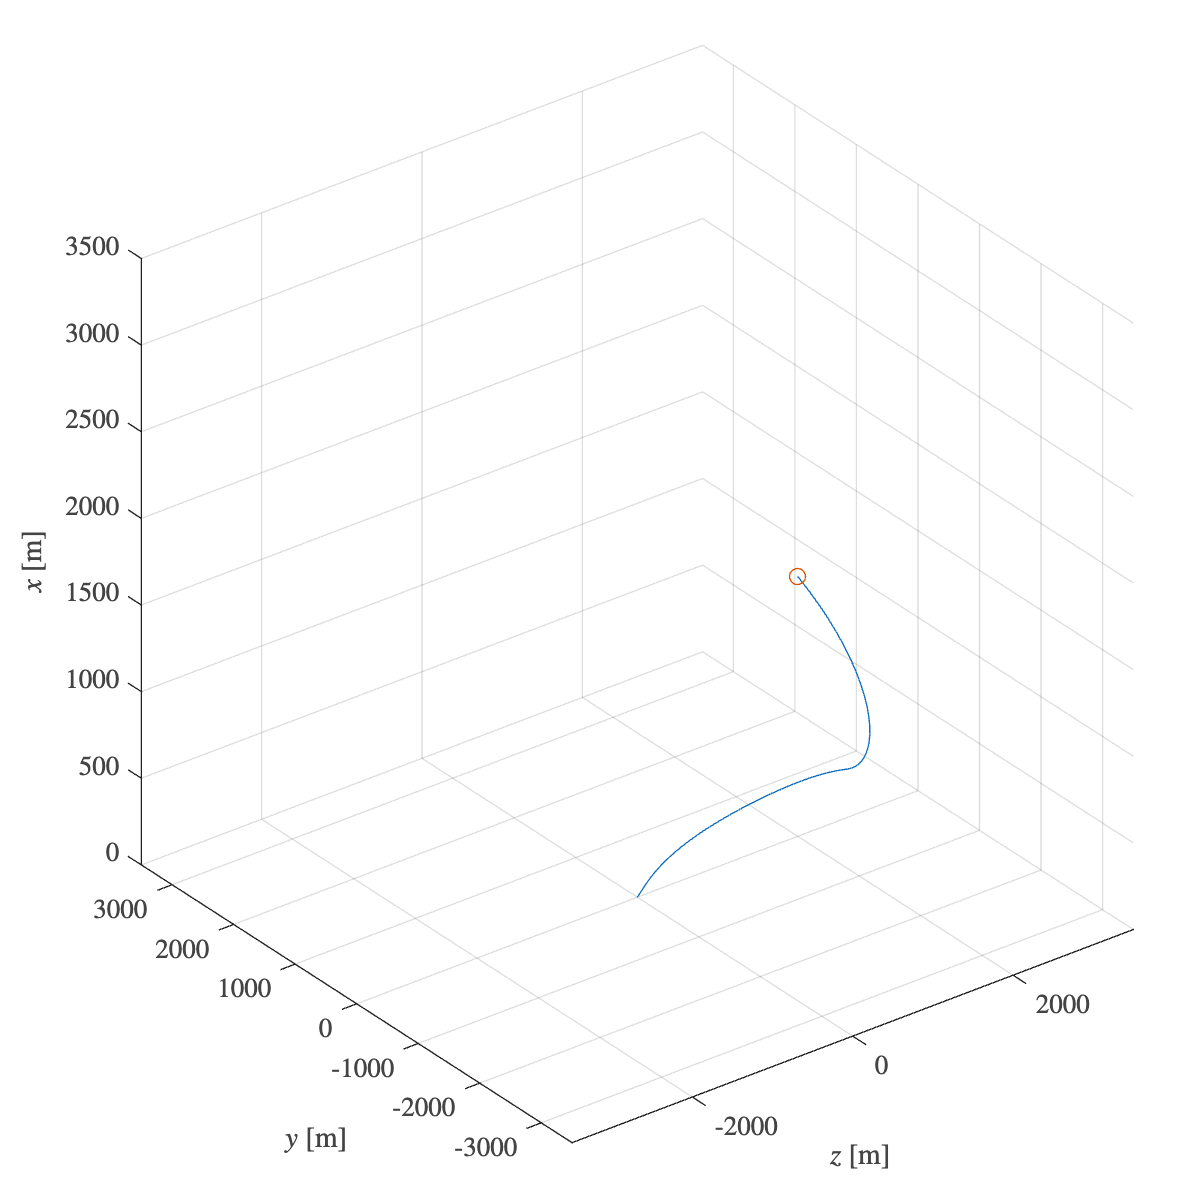

figure(1)
trajectory = tiledlayout(1, 1, "TileSpacing", "compact", "Padding", "compact");
set(gcf, 'Position', [100 100 600 600])
nexttile
plot3(state_history(3,:), state_history(2,:), state_history(1,:))
hold on
plot3(r0(3), r0(2), r0(1), 'o')
xlabel('$z$ [m]')
ylabel('$y$ [m]')
zlabel('$x$ [m]')
xlim([-3500 3500])
ylim([-3500 3500])
zlim([0 3500])
grid on

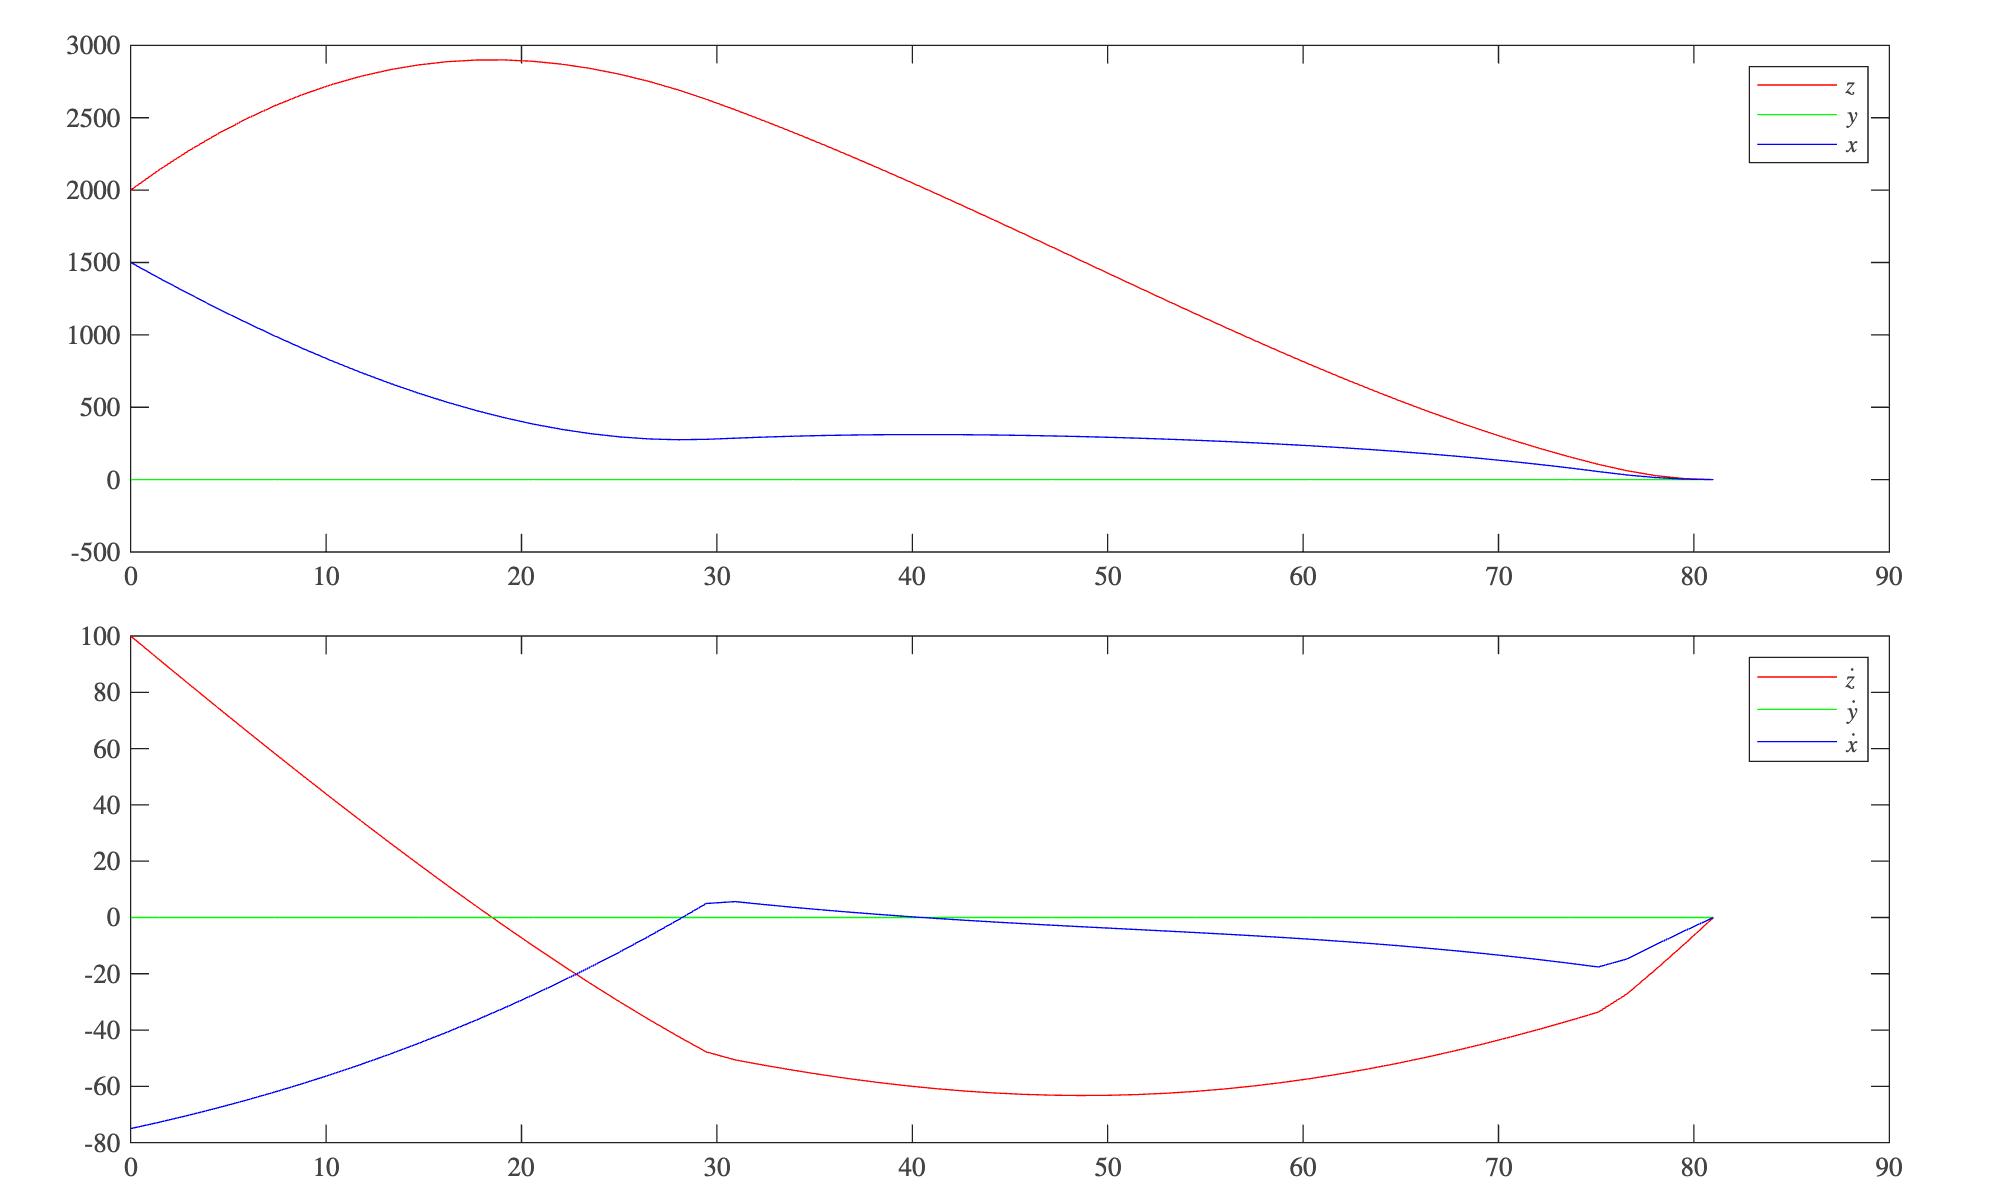

tspan = 0:delta_t:N*delta_t;

figure(2)
state_plot = tiledlayout(2, 1, "TileSpacing", "compact", "Padding", "compact");
set(gcf, "Position", [100 100 1000 600])

nexttile
plot(tspan, state_history(3,:), 'r', tspan, state_history(2, :), 'g', tspan, state_history(1, :), 'b')
legend('$z$', '$y$', '$x$')

nexttile
plot(tspan, state_history(6,:), 'r', tspan, state_history(5, :), 'g', tspan, state_history(4, :), 'b')
legend('$\dot{z}$', '$\dot{y}$', '$\dot{x}$')